Accelreation equation of a sky-diver:


$$a\left(v\right)=g\left(1-\frac{v^{2\;} }{3600}\right);$$



$$g=9\ldotp 81\;\frac{m}{s^{2\;} };\;\Delta v=0\ldotp 1\;\frac{m}{s}$$


Compute and plot $a\left(v\right)$ vs $v$

v = 0:.1:100;
g=9.81

g = 9.8100

a = g*(1-v.^2/3600)

a =     9.8100    9.8100    9.8099    9.8098    9.8096    9.8093    9.8090    9.8087    9.8083    9.8078    9.8073    9.8067    9.8061    9.8054    9.8047    9.8039    9.8030    9.8021    9.8012    9.8002    9.7991    9.7980    9.7968    9.7956    9.7943    9.7930    9.7916    9.7901    9.7886    9.7871    9.7855    9.7838    9.7821    9.7803    9.7785    9.7766    9.7747    9.7727    9.7707    9.7686    9.7664    9.7642    9.7619    9.7596    9.7572    9.7548    9.7523    9.7498    9.7472    9.7446


plot(v, a, 'ro-'), grid on
xlabel('v, Velocity [m/s]')
ylabel('a(v), Acceleration [m/s^2]')

Compute the terminal speed of a sky-diver in $\frac{m}{s}:$

Tt = find(a<=0);  % Terminal acceleration
v_t= v(Tt(1))     % Terminal velocity

v_t = 60

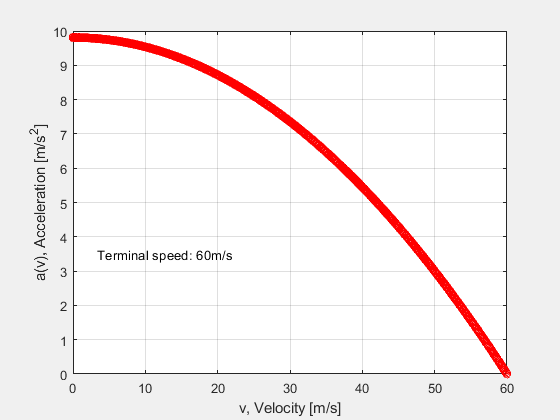

gtext(['Terminal speed: '  num2str(v_t)  'm/s'])
xlim([0, v_t])